%%大气透射率分布云图绘制
    S = 10;
    scatter(xy(:,1),xy(:,2),S,eta_at,'filled')
    colormap("jet");
    h = colorbar;
    hold on;
    plot(0,0,'ro-','MarkerFaceColor','r','MarkerSize',10);
    set(get(h,'label'));%给颜色栏命名

        BackgroundColor: {1×0 cell}
             BusyAction: {'queue'  'cancel'}
          ButtonDownFcn: {}
               Children: {}
               Clipping: {[on]  [off]}
                  Color: {1×0 cell}
            ContextMenu: {}
              CreateFcn: {}
              DeleteFcn: {}
              EdgeColor: {1×0 cell}
                Editing: {[on]  [off]}
              FontAngle: {'normal'  'italic'}
               FontName: {}
               FontSize: {}
          FontSmoothing: {[on]  [off]}
              FontUnits: {'inches'  'centimeters'  'normalized'  'points'  'pixels'}
             FontWeight: {'normal'  'bold'}
       HandleVisibility: {'on'  'callback'  'off'}
                HitTest: {[on]  [off]}
    HorizontalAlignment: {'left'  'center'  'right'}
            Interpreter: {'none'  'tex'  'latex'}
          Interruptible: {[on]  [off]}
              LineStyle: {'-'  '--'  ':'  '-.'  'none'}
              LineWidth: {}
                 Margin: {}
               

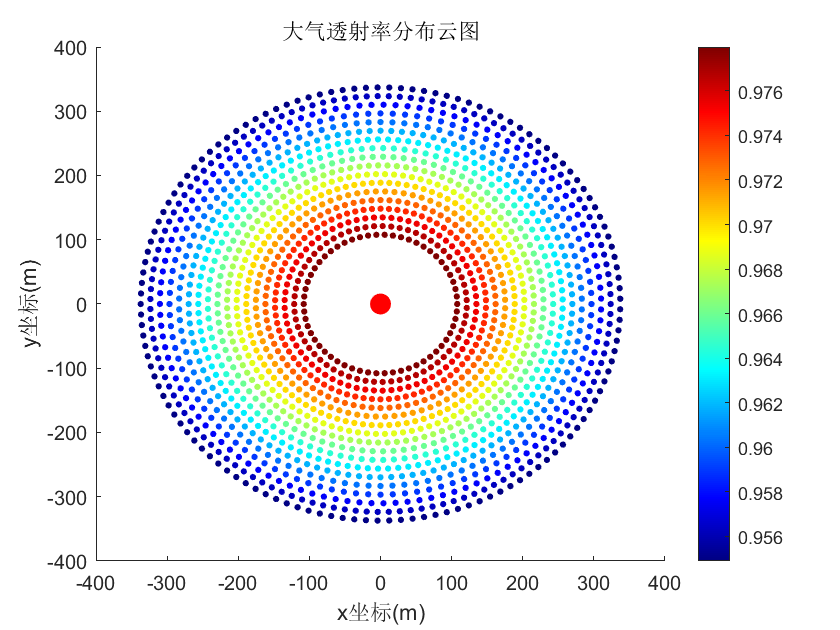

    xlabel('x坐标(m)');
    ylabel('y坐标(m)');
    title('大气透射率分布云图');
    saveas(gca,'eta_at.png');
    hold off;

%%大气透射率与距离的关系
    temp = [d_HR,eta_at];
    temp = sortrows(temp)

temp =   132.5425    0.9780
  132.5425    0.9780
  132.5426    0.9780
  132.5426    0.9780
  132.5426    0.9780
  132.5426    0.9780
  132.5426    0.9780
  132.5426    0.9780
  132.5426    0.9780
  132.5426    0.9780


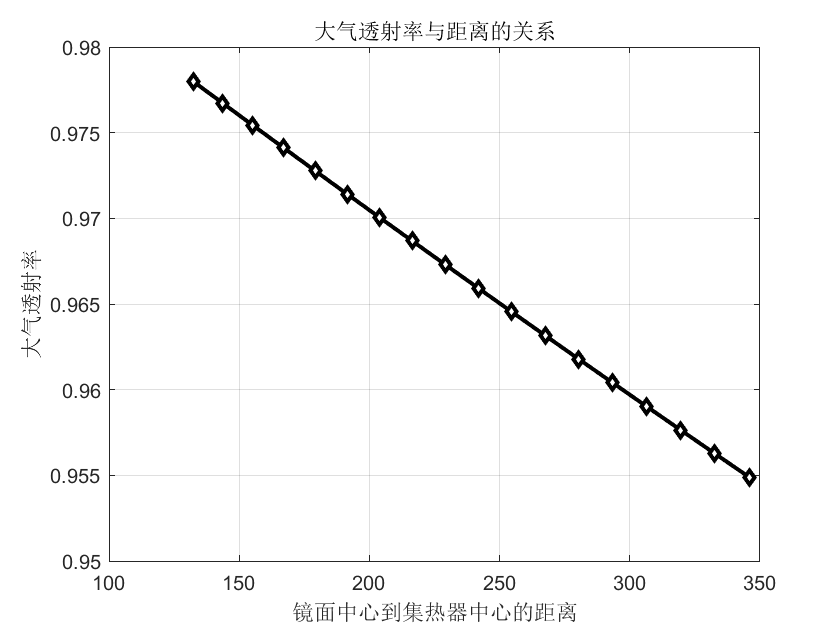

    plot(temp(:,1),temp(:,2),'-dk','MarkerSize',5,'LineWidth',2,'MarkerFaceColor','w','MarkerEdgeColor','k')
    xlabel('镜面中心到集热器中心的距离');
    ylabel('大气透射率');
    grid on;
    title('大气透射率与距离的关系');
    saveas(gca,'eta_at_dis.png');